Effectiveness profiling of RSQP from wind tunnel data

ismac = 0;
if ismac
    p = parselog('/Users/tomasodeponti/Desktop/19_21_53 2/22_02_10__19_21_53.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data\16_51_51_cyberzoo\16_51_51_cyberzoo\80_01_08__17_50_59_SD.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end

ac_data = p.aircrafts.data;
%%%%%  plot(t,pwm2pprz(act6,pwm_as,pprz_as));hold on;plot(t,ac_data.EFF_FULL_INDI.doublet_active.*100);plot(t,as2)
%%%%%  plot(t,pwm2pprz(act6,pwm_as,pprz_as));hold on;plot(t,ac_data.EFF_FULL_INDI.doublet_active.*100);plot(t,d_cv(:,6))

Select filtering criteria

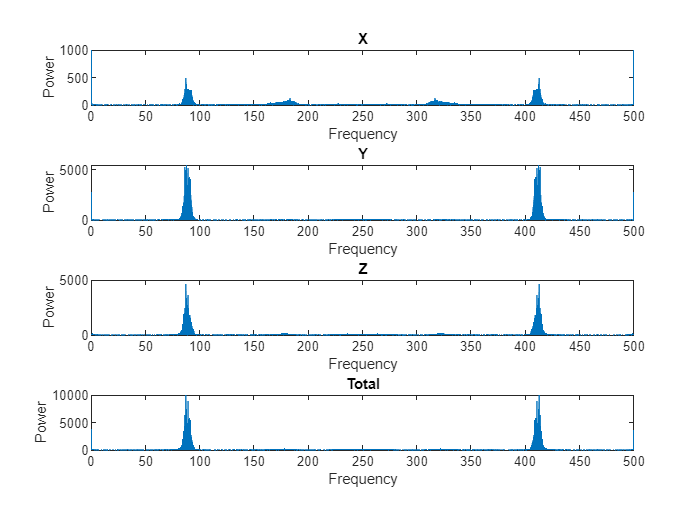

la_x = ac_data.EFF_FULL_INDI.body_accel_x - mean(ac_data.EFF_FULL_INDI.body_accel_x);
la_y = ac_data.EFF_FULL_INDI.body_accel_y - mean(ac_data.EFF_FULL_INDI.body_accel_y);
la_z = ac_data.EFF_FULL_INDI.body_accel_z - mean(ac_data.EFF_FULL_INDI.body_accel_z);

y_x = fft(la_x);
y_y = fft(la_y);
y_z = fft(la_z);

n = length(la_x);          % number of samples
fs = get_sf(ac_data.EFF_FULL_INDI.timestamp);
f = (0:n-1)*(fs/n);     % frequency range
power_x = abs(y_x).^2/n;    % power of the DFT
power_y = abs(y_y).^2/n;
power_z = abs(y_z).^2/n;
power   = power_x + power_y + power_z;

figure(101)
subplot(4,1,1)
plot(f,power_x)
xlabel('Frequency')
ylabel('Power')
title('X')

subplot(4,1,2)
plot(f,power_y)
xlabel('Frequency')
ylabel('Power')
title('Y')

subplot(4,1,3)
plot(f,power_z)
xlabel('Frequency')
ylabel('Power')
title('Z')

subplot(4,1,4)
plot(f,power)
xlabel('Frequency')
ylabel('Power')
title('Total')


f_filter = 1.5;%1.45;%3;

Prepare acceleration signal

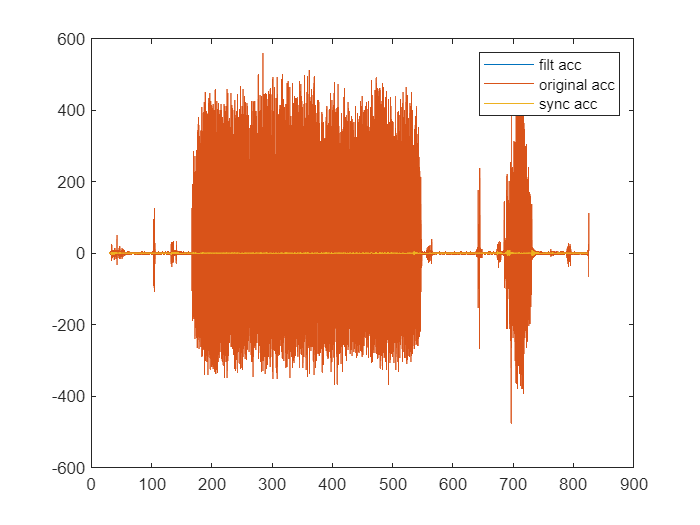

t = ac_data.EFF_FULL_INDI.timestamp;
p = ac_data.EFF_FULL_INDI.angular_rate_p;
q = ac_data.EFF_FULL_INDI.angular_rate_q;
r = ac_data.EFF_FULL_INDI.angular_rate_r;

sf = get_sf(t);
[b,a] = butter(6,f_filter/(sf/2),'low')  ;
[gd,w] = grpdelay(b,a,512);
delay = round(0.86*mean(gd(w<(2*pi*f_filter/sf))));
delay_t = delay/sf;
a_p = low_butter(diff_scaled(p,t),f_filter,sf,0);
a_q = low_butter(diff_scaled(q,t),f_filter,sf,0);
a_r = low_butter(diff_scaled(r,t),f_filter,sf,0);
acc = [a_p,a_q,a_r];

figure(70)
clf
plot(t(2:end),a_p)
hold on
plot(t(2:end),diff_scaled(p,t))
plot(t(2:end)-delay_t,a_p)
legend("filt acc","original acc","sync acc")

Prepare actuator command signal 0-9600

act_names = ["Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];
act = cellfun(@(S) sscanf(S, '%f,').', ac_data.EFF_FULL_INDI.u, 'Uniform', 0);
act = cell2mat(act);
d_cv = cellfun(@(S) sscanf(S, '%f,').', ac_data.EFF_FULL_INDI.current_doublet_values, 'Uniform', 0);
d_cv = cell2mat(d_cv);

% act1 = low_butter(act(:,1),f_filter,sf,0);
% act2 = low_butter(act(:,2),f_filter,sf,0);
% act3 = low_butter(act(:,3),f_filter,sf,0);
% act4 = low_butter(act(:,4),f_filter,sf,0);
% act5 = low_butter(act(:,5),f_filter,sf,0);
% act6 = low_butter(act(:,6),f_filter,sf,0);
% act7 = low_butter(act(:,7),f_filter,sf,0);
% act8 = low_butter(act(:,8),f_filter,sf,0);

pwm_as = [1100,1900];
pwm_mot = [1000,2000];
pprz_as = [-9600,9600];
pprz_mot = [0,9600];

rate_lim = 1230000;
fo_mot = 24.5;%6;%24.5; % rad/s
fo_as  = 52.8;  %       % rad/s

m1 = pwm2pprz(pp_limiter(act(:,1),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);

A =
 
   0.04782
  ----------
  z - 0.9522
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.0478

beta = 0.9522

m2 = pwm2pprz(pp_limiter(act(:,2),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);

A =
 
   0.04782
  ----------
  z - 0.9522
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.0478

beta = 0.9522

m3 = pwm2pprz(pp_limiter(act(:,3),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);

A =
 
   0.04782
  ----------
  z - 0.9522
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.0478

beta = 0.9522

m4 = pwm2pprz(pp_limiter(act(:,4),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);

A =
 
   0.04782
  ----------
  z - 0.9522
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.0478

beta = 0.9522

as1 = pwm2pprz(pp_limiter(act(:,5),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);

A =
 
    0.1002
  ----------
  z - 0.8998
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.1002

beta = 0.8998

as2 = pwm2pprz(pp_limiter(act(:,6),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);

A =
 
    0.1002
  ----------
  z - 0.8998
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.1002

beta = 0.8998

as3 = pwm2pprz(pp_limiter(act(:,7),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);

A =
 
    0.1002
  ----------
  z - 0.8998
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.1002

beta = 0.8998

as4 = pwm2pprz(pp_limiter(act(:,8),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);

A =
 
    0.1002
  ----------
  z - 0.8998
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.1002

beta = 0.8998


pf = low_butter(p,f_filter,sf,0);
qf = low_butter(q,f_filter,sf,0);
rf = low_butter(r,f_filter,sf,0);

damping = 0;

if damping
    act_aug = [m1,m2,m3,m4,as1,as2,as3,as4,ones(size(m1)),pf,qf,rf];
else
    act_aug = [m1,m2,m3,m4,as1,as2,as3,as4,ones(size(m1))];
end

Let's perform an analysis of the effects of filtering and actuator dynamics

%temp_save=as2;
dt = 0;
j=6

j = 6

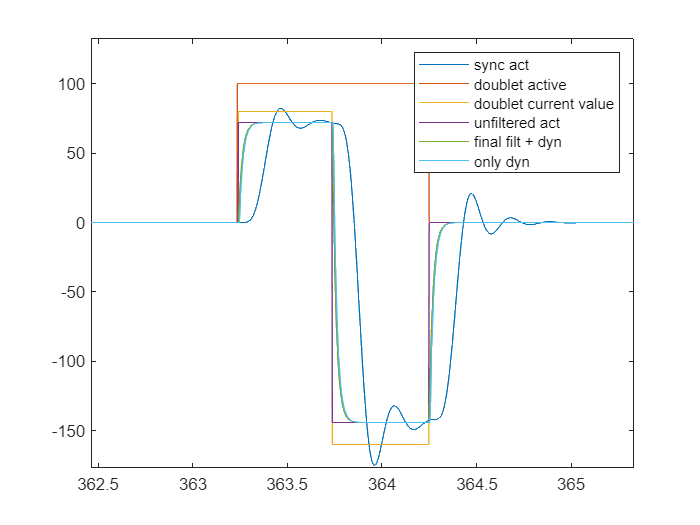

figure(69)
clf
plot(t,pwm2pprz(act6,pwm_as,pprz_as))
hold on
plot(t+dt,ac_data.EFF_FULL_INDI.doublet_active.*100)
plot(t+dt,d_cv(:,j))
plot(t+dt,pwm2pprz(act(:,j),pwm_as,pprz_as))
plot(t+dt,as2)
plot(t+dt,temp_save)
legend("sync act","doublet active","doublet current value","unfiltered act","final filt + dyn","only dyn")

Select only timestamps where doublets were performed to estimate the effectiveness of the actuators.

Motor Front


    0.0000    0.0005    0.0001
   -0.3495   -3.6591   -0.8924



Motor Front


    0.0000    0.0009    0.0000
   -0.3135   -6.2915   -0.2047



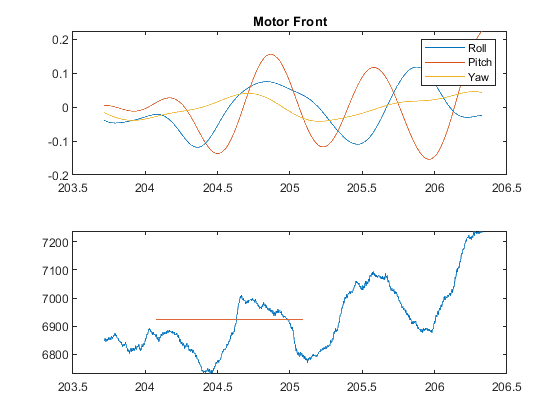

Motor Right


   -0.0005   -0.0001   -0.0002
    3.3126    0.7677    1.4156



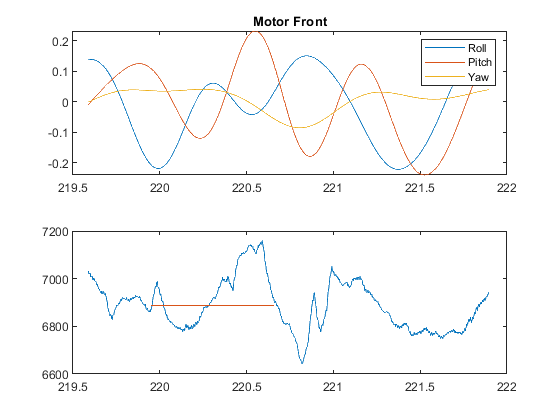

Motor Right


   -0.0017   -0.0003   -0.0004
   11.7591    2.2104    2.9934



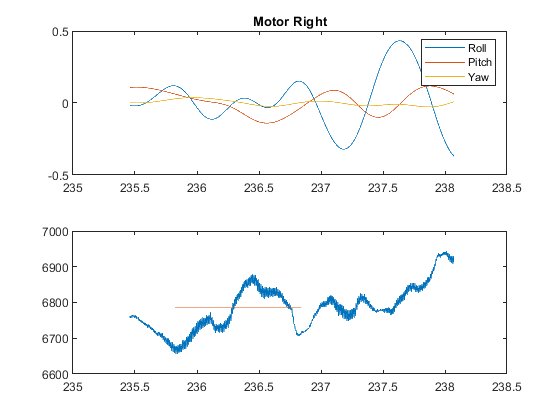

Motor Back


   -0.0003   -0.0004    0.0002
    2.4147    2.8460   -1.1304



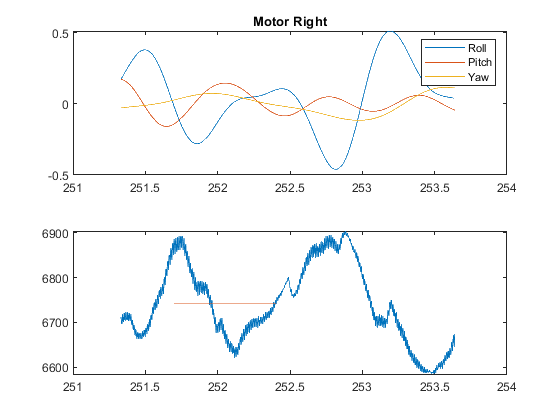

Motor Back


    0.0008    0.0000    0.0000
   -5.4791   -0.2475   -0.2684



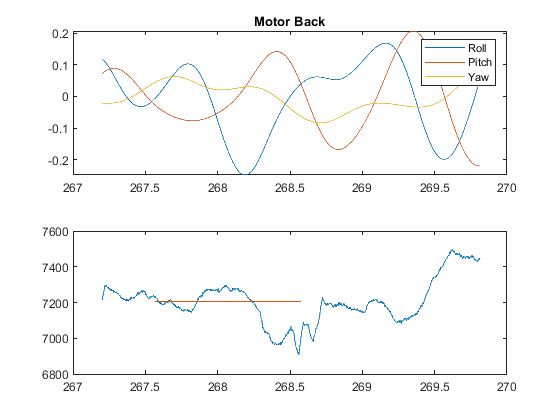

Motor Left


    0.0034    0.0004    0.0001
  -22.3151   -2.6923   -0.8769



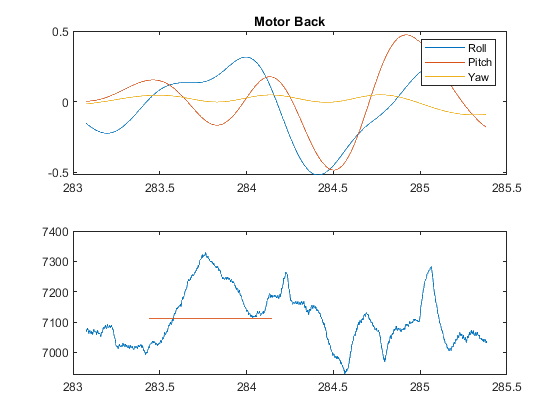

Motor Left


    0.0005    0.0001   -0.0001
   -3.5953   -0.6593    0.3468



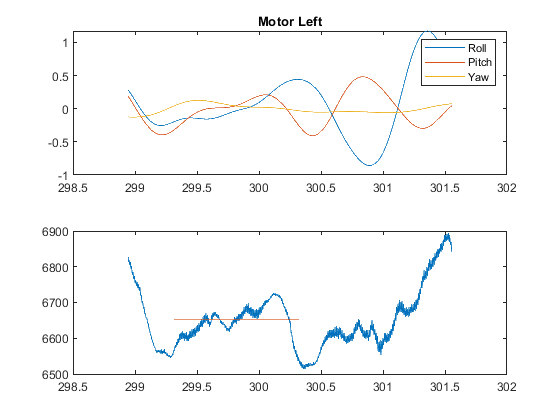

Aileron Left


   -0.0003   -0.0006    0.0004
   -0.0156   -0.0183   -0.0044



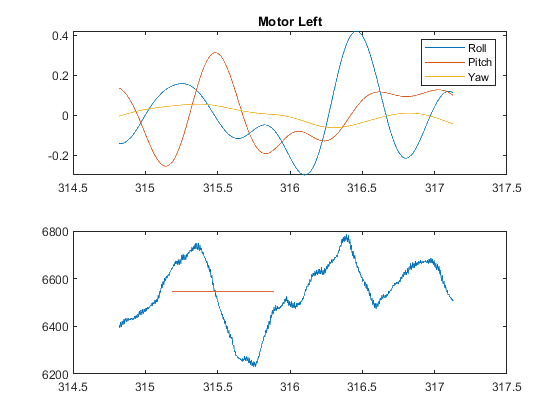

Aileron Left


    0.0043    0.0012    0.0001
    0.0238    0.0030   -0.0102



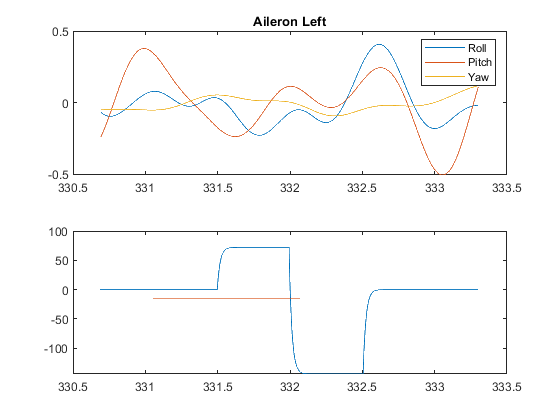

Aileron Right


    0.0011    0.0008    0.0009
    0.0625    0.0270    0.0182



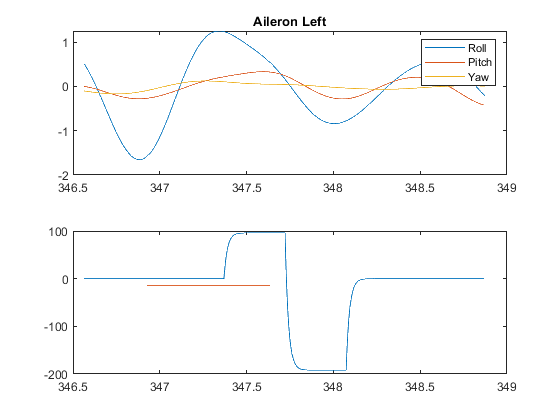

Aileron Right


   -0.0031   -0.0009    0.0003
   -0.0439    0.0034    0.0251



Elevator


   -0.0011    0.0009   -0.0000
   10.7126   -8.5616    0.2798



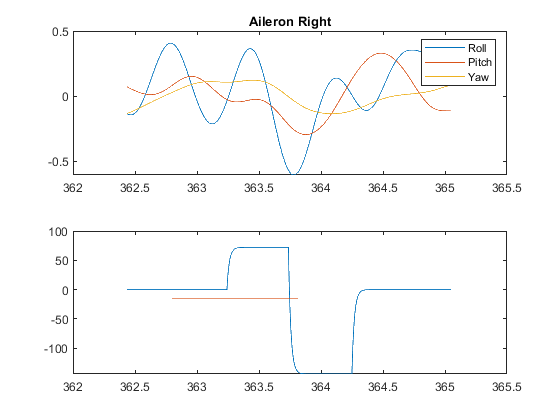

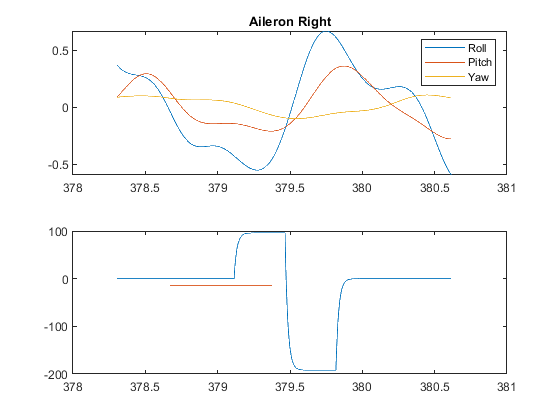

Elevator


   -0.0002   -0.0004    0.0003
    2.3191    3.6360   -2.7660



Rudder


   -0.0027   -0.0021   -0.0001
   25.3538   19.9825    1.2876



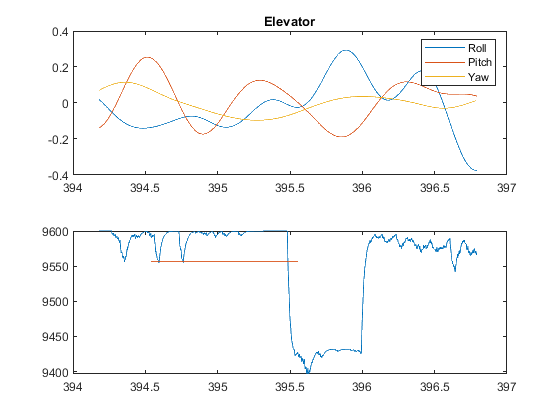

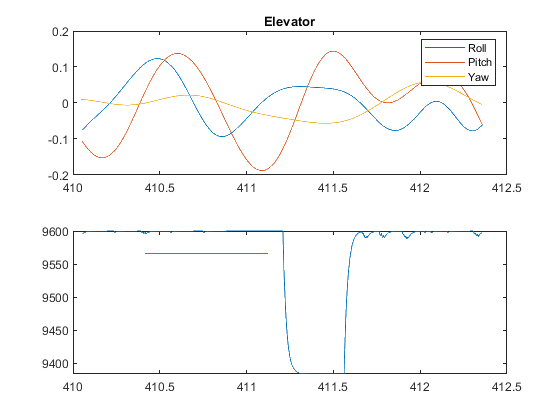

Rudder


   -0.0006    0.0003    0.0001
    6.0721   -2.4542   -0.9254



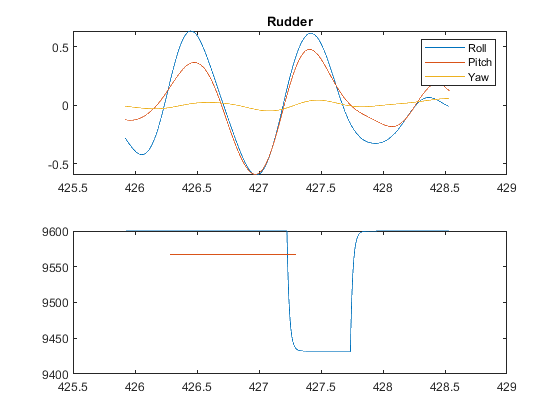

offset = 0

     1



    "Actuator"         "Roll"         "Pitch"        "Yaw"       
    "Motor Front"      "0.41706"      "0.52098"      "0.049646"  
    "Motor Right"      "-0.67121"     "-0.24431"     "-0.054158" 
    "Motor Back"       "-0.37035"     "-0.58878"     "0.075854"  
    "Motor Left"       "1.0869"       "0.55235"      "-0.057682" 
    "Aileron Left"     "1.9471"       "0.22917"      "0.20788"   
    "Aileron Right"    "-0.55179"     "0.31131"      "0.49874"   
    "Elevator"         "0.0050217"    "0.0071531"    "-0.0020596"
    "Rudder"           "0.23838"      "0.10428"      "-0.07008"  



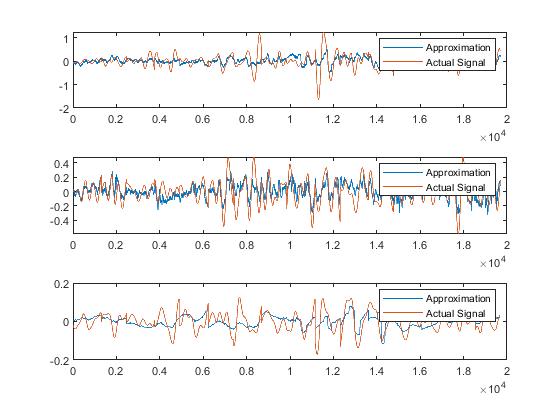

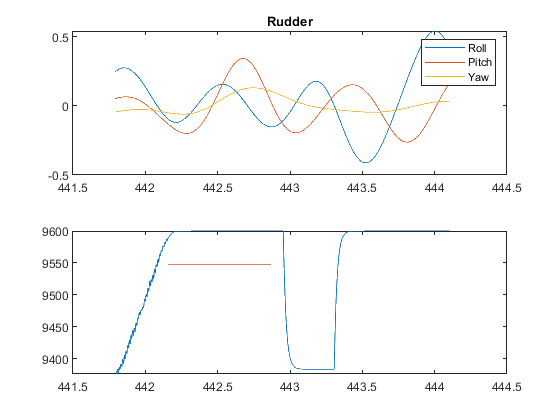

    0.2694    0.1372    0.0449




idx_save = [];
save_mat = [];
slack = 0.8;%0.2;
n_idx = slack*sf;
s_idx = linspace(-1*n_idx,-1,n_idx).';
e_idx = linspace(1,1*n_idx,n_idx).';
doublet_amp   = [40,50; 30, 40;40,50; 30, 40; 80 100;80 100; 80 100; 80 100];
n_m = 16;
debug = 1;
n_wing_sp = 1;
act_num = 8;
for i=1:n_m*n_wing_sp
    
    %idx_s = t_finder(t,t_s(i)-slack);
    %idx_e = t_finder(t,t_e(i)+slack);
    %if i <= n_m
    n = fix(i/2)+mod(i,2)- 8 * fix(i/(n_m+1));
    idx_range = find((ac_data.EFF_FULL_INDI.doublet_active==1).*(ac_data.EFF_FULL_INDI.doublet_axis==(n-1)).*(ac_data.EFF_FULL_INDI.doublet_amplitude==doublet_amp(n,2-mod(i,2))));
    range_clean = idx_range;
    idx_range = [idx_range(1)+s_idx;idx_range;idx_range(end)+e_idx];
    idx_save = [idx_save;idx_range];
    %%%%%%%%%n = fix(i/2)+mod(i,2)- 8 * fix(i/(n_m+1));
    
    if debug
            act_aug_d = [act_aug(idx_range,n),act_aug(idx_range,end)];
            acc_d = acc(idx_range+delay,:);
            effectiveness_mat = act_aug_d\acc_d;
            disp(act_names(n))
            disp(effectiveness_mat)

            figure(i)
            clf
            
            ax1=subplot(2,1,1);
            plot(t(idx_range),acc_d)
            legend("Roll","Pitch","Yaw")
            title(act_names(n))
            ax2=subplot(2,1,2);
            plot(t(idx_range),act_aug_d(:,1))
            hold on
            plot(t(range_clean-delay),ones(size(t(range_clean))).*mean(act_aug_d(:,1)))
            
            linkaxes([ax1,ax2],'x');
            hold off
    end
    %end
    if mod(i,n_m) == 0 %perform full estimation
        %idx_save = idx_save.';
        act_aug_d = act_aug(idx_save,1:end);
        acc_d = acc(idx_save+delay,:);
        effectiveness_mat = act_aug_d\acc_d;
        magnifying = 1000;
        save_mat = [save_mat,effectiveness_mat];
        math_mat = effectiveness_mat;
        effectiveness_mat = effectiveness_mat * magnifying;
        offset = 0 

        if damping
            effectiveness_mat = [[act_names(1:8).';"offset";"damp p";"damp q";"damp r"], effectiveness_mat(1:end,:)];
            effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];
        else
            effectiveness_mat = [act_names(1:8).', effectiveness_mat(1:end-1,:)];
            effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];
        end
        
        disp(fix(i/n_m))
        disp(effectiveness_mat)
        approx = act_aug_d * math_mat;
        figure(200+fix(i/n_m))
        clf
        ax1=subplot(3,1,1);
        plot(approx(:,1))
        hold on
        plot(acc_d(:,1))
        legend("Approximation","Actual Signal")
        
        ax2=subplot(3,1,2);
        plot(approx(:,2))
        hold on
        plot(acc_d(:,2))
        legend("Approximation","Actual Signal")
        
        ax3=subplot(3,1,3);
        plot(approx(:,3))
        hold on
        plot(acc_d(:,3))
        legend("Approximation","Actual Signal")
        linkaxes([ax1,ax2,ax3],'x');
        hold off

        RMSE = sqrt(mean((acc_d - approx).^2));
        idx_save = [];
        disp(RMSE)
        
    end
end

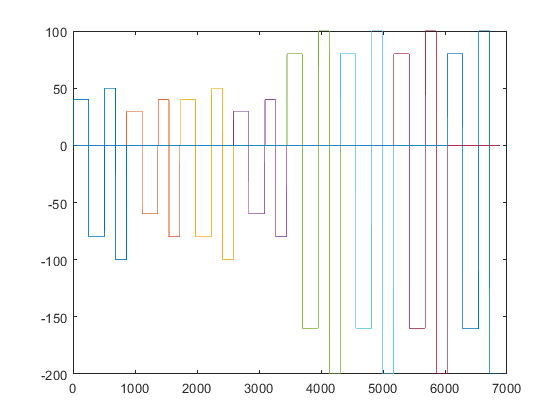

figure(345)
plot(d_cv(ac_data.EFF_FULL_INDI.doublet_active==1,:))

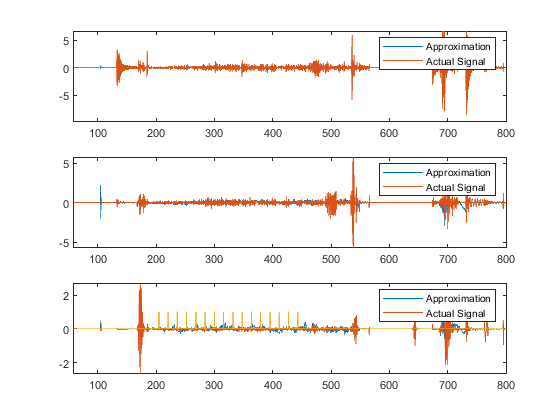

wtf = act_aug(2:end,:)\acc;
approx2 = act_aug(2:end,:) * wtf;
figure(303)
clf
ax1=subplot(3,1,1);
 plot(t(2:end),approx2(:,1))
        hold on
        plot(t(2:end),acc(:,1))
        legend("Approximation","Actual Signal")
        
        ax2=subplot(3,1,2);
        plot(t(2:end),approx2(:,2))
        hold on
        plot(t(2:end),acc(:,2))
        legend("Approximation","Actual Signal")
        
        ax3=subplot(3,1,3);
        plot(t(2:end),approx2(:,3))
        hold on
        plot(t(2:end),acc(:,3))
        plot(t,ac_data.EFF_FULL_INDI.doublet_active)
        legend("Approximation","Actual Signal")
        linkaxes([ax1,ax2,ax3],'x');
        hold off

for j =1:(size(save_mat,2)/3-1)
    k = j-1;
    delta_mat = round((save_mat(:,1+j*3:3+j*3)-save_mat(:,1+k*3:3+k*3))./save_mat(:,1+k*3:3+k*3).*100,2);
    disp("Delta Mat")
    disp(j)
    format longG
    if damping
        disp(["Actuator","Roll","Pitch","Yaw";[[act_names(1:8).';"offset";"damp p";"damp q";"damp r"],delta_mat]])
    else
        disp(["Actuator","Roll","Pitch","Yaw";[act_names(1:8).',delta_mat(1:end-1,:)]])
    end
    
end

Perform estimation over multiple doublets to reduce bias error


idx_save = idx_save.';
act_aug_d = act_aug(idx_save,1:end);
acc_d = acc(idx_save,:);
effectiveness_mat = act_aug_d\acc_d;
magnifying = 1000;
save_mat = effectiveness_mat;
effectiveness_mat = effectiveness_mat * magnifying;
effectiveness_mat = [act_names(1:8).', effectiveness_mat(1:end-1,:)];
effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];

disp(effectiveness_mat)

    "Actuator"         "Roll"    "Pitch"    "Yaw"
    "Motor Front"      "0"       "0"        "0"  
    "Motor Right"      "0"       "0"        "0"  
    "Motor Back"       "0"       "0"        "0"  
    "Motor Left"       "0"       "0"        "0"  
    "Aileron Left"     "0"       "0"        "0"  
    "Aileron Right"    "0"       "0"        "0"  
    "Elevator"         "0"       "0"        "0"  
    "Rudder"           "0"       "0"        "0"  



test results 

approx = act_aug_d * save_mat;
figure(20)
clf
ax1=subplot(3,1,1);
plot(approx(:,1))
hold on
plot(acc_d(:,1))
legend("Approximation","Actual Signal")


ax2=subplot(3,1,2);
plot(approx(:,2))
hold on
plot(acc_d(:,2))
legend("Approximation","Actual Signal")


ax3=subplot(3,1,3);
plot(approx(:,3))
hold on
plot(acc_d(:,3))
legend("Approximation","Actual Signal")

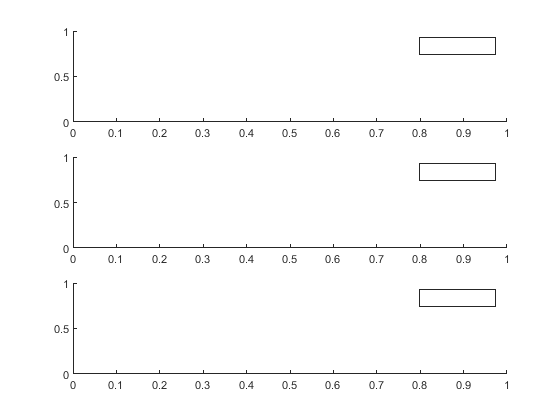

% ax1=subplot(3,1,1);
% plot(t(idx_save),approx(:,1))
% hold on
% plot(t(idx_save),acc_d(:,1))
% legend("Approximation","Actual Signal")
% 
% ax2=subplot(3,1,2);
% plot(t(idx_save),approx(:,2))
% hold on
% plot(t(idx_save),acc_d(:,2))
% legend("Approximation","Actual Signal")
% 
% ax3=subplot(3,1,3);
% plot(t(idx_save),approx(:,3))
% hold on
% plot(t(idx_save),acc_d(:,3))
% legend("Approximation","Actual Signal")

linkaxes([ax1,ax2,ax3],'x');

RMSE = sqrt(mean((acc_d - approx).^2));